% ==========================================================
% main_generator.m - 主数据生成脚本
% ==========================================================
clear; clc; close all;

% --- 1. 公共参数设置 ---
params.fs = 80e6;       % 采样频率 100MHz
params.fc = 40e6;        % 中心频率 40MHz
params.B = 10e6;         % 带宽    10MHz
params.taup = 10e-6;     % LFM脉宽 10us
params.Np = 1;          % 脉冲个数 16
params.PRI = 200e-6;     % 脉冲重复间隔
params.SNR = 15;         % 信噪比
params.JNR = 15;         % 干信比 (可以为不同干扰类型单独设置)
params.pos = 5000;       %在PRI中第5000点处
JNR_values = 10:5:20;    % 信噪比范围 dB


% --- 2. 生成计划 ---
% 定义要生成的干扰类型和对应的标签
generation_plan = {
    % 欺骗干扰
    'DFTJ', 1, 50;
    'ISRJ', 2, 50;
    'RGPO' , 3, 50;
    'VGPO' , 4, 50;
    % 压制干扰
    'AJ'  , 5, 50;
    'BJ'  , 6, 50;
    'SJ'  , 7, 50;
    'NCJ' , 8, 50;
    'NPJ' , 9, 50;
    % 在这里添加更多类型，例如 'sweep', 3, 200
    };

% --- 3. 初始化数据容器 ---
all_samples = [];
all_labels = [];

% --- 4. 执行生成 ---



## 循环生成每种干扰

len = size(generation_plan, 1)

len = 9

for current_jnr = JNR_values
    % 初始化数据容器
    all_samples = [];
    all_labels = [];
    all_S = zeros(450,64,249);
    for i = 1:len
        % 生成基础目标信号 (所有干扰类型共用)
        params.pos = 5000+randi([-2000 2000]);
        [tx, params] = generate_0base_signal(params);

        jam_type = generation_plan{i, 1};
        label = generation_plan{i, 2};
        num_to_generate = generation_plan{i, 3};
        fprintf('正在生成 %d 个 [%s] 类型的样本, 标签为 %d...\n', num_to_generate, jam_type, label);

        Aj = 10^(current_jnr/20);
        % 创建当前SNR值的子文件夹
        snr_output_dir = fullfile('data2501114', sprintf('JNR_%+d', current_jnr));
        if ~exist(snr_output_dir, 'dir')
            mkdir(snr_output_dir);
        end
        fprintf('Generating data for JNR = %d dB...\n', current_jnr);

        switch jam_type
            case 'DFTJ'
                jam_params = params;
                jam_params.JNR = current_jnr; % 密集假目标干扰
                [new_samples, new_labels] = generate_1dftj_jamming(tx, jam_params, label, num_to_generate);
                all_samples = [all_samples; new_samples];
                all_labels = [all_labels; new_labels];
            case 'ISRJ'
                jam_params = params;
                jam_params.JNR = current_jnr; % 间歇采样转发干扰
                [new_samples, new_labels] = generate_2isrj_jamming(tx, jam_params, label, num_to_generate);
                all_samples = [all_samples; new_samples];
                all_labels = [all_labels; new_labels];
            case 'RGPO'
                jam_params = params;
                jam_params.JNR = current_jnr; % 距离假目标干扰
                jam_params.v = 5e5;           % 拖引速率
                [new_samples, new_labels] = generate_3rgpo_jamming(tx, jam_params, label, num_to_generate);
                all_samples = [all_samples; new_samples];
                all_labels = [all_labels; new_labels];
            case 'VGPO'
                jam_params = params;
                jam_params.JNR = current_jnr; % 速度假目标干扰
                jam_params.pull = 5e5;        % 拖引频率 Hz
                [new_samples, new_labels] = generate_4vgpo_jamming(tx, jam_params, label, num_to_generate);
                all_samples = [all_samples; new_samples];
                all_labels = [all_labels; new_labels];
            case 'AJ'
                jam_params = params;
                jam_params.JNR = current_jnr; % 瞄准干扰通常功率更集中
                jam_params.BJ = 20e6;         % 干扰带宽 20MHz
                [new_samples, new_labels] = generate_5ab_jamming(tx, jam_params, label, num_to_generate);
                all_samples = [all_samples; new_samples];
                all_labels = [all_labels; new_labels];
            case 'BJ'
                jam_params = params;
                jam_params.JNR = current_jnr; % 阻塞干扰
                jam_params.BJ = 45e6;         % 干扰带宽 45MHz
                [new_samples, new_labels] = generate_5ab_jamming(tx, jam_params, label, num_to_generate);
                all_samples = [all_samples; new_samples];
                all_labels = [all_labels; new_labels];
            case 'SJ'
                jam_params = params;
                jam_params.JNR = current_jnr;  % 扫频干扰
                jam_params.BJ = 10e6;          % 干扰带宽 5MHz
                [new_samples, new_labels] = generate_7sj_jamming(tx, jam_params, label, num_to_generate);
                all_samples = [all_samples; new_samples];
                all_labels = [all_labels; new_labels];
            case 'NCJ'
                jam_params = params;
                jam_params.JNR = current_jnr; % 噪声卷积干扰
                [new_samples, new_labels] = generate_8ncj_jamming(tx, jam_params, label, num_to_generate);
                all_samples = [all_samples; new_samples];
                all_labels = [all_labels; new_labels];
            case 'NPJ'
                jam_params = params;
                jam_params.JNR = current_jnr; % 噪声乘积干扰
                [new_samples, new_labels] = generate_9npj_jamming(tx, jam_params, label, num_to_generate);
                all_samples = [all_samples; new_samples];
                all_labels = [all_labels; new_labels];
        end
        % 追加到总数据集中
    end
    for i = 1:450
    [S,F,T] = spectrogram(all_samples(1,:),128,128-64,64,params.fs, 'centered');
    all_S(i,:,:) = S;
    end

    all_stft = fullfile(snr_output_dir, 'echo_stft.mat');
    save(all_stft, 'all_S', '-v7.3');

    all_time = fullfile(snr_output_dir, 'echo_time.mat');
    all_label = fullfile(snr_output_dir, 'echo_label.mat');
    save(all_time, 'all_samples', '-v7.3');
    save(all_label, 'all_labels', '-v7.3');
end

正在生成 50 个 [DFTJ] 类型的样本, 标签为 1...


Generating data for JNR = 10 dB...


正在生成 50 个 [ISRJ] 类型的样本, 标签为 2...


Generating data for JNR = 10 dB...


正在生成 50 个 [RGPO] 类型的样本, 标签为 3...


Generating data for JNR = 10 dB...


正在生成 50 个 [VGPO] 类型的样本, 标签为 4...


Generating data for JNR = 10 dB...


正在生成 50 个 [AJ] 类型的样本, 标签为 5...


Generating data for JNR = 10 dB...


正在生成 50 个 [BJ] 类型的样本, 标签为 6...


Generating data for JNR = 10 dB...


正在生成 50 个 [SJ] 类型的样本, 标签为 7...


Generating data for JNR = 10 dB...


正在生成 50 个 [NCJ] 类型的样本, 标签为 8...


Generating data for JNR = 10 dB...


正在生成 50 个 [NPJ] 类型的样本, 标签为 9...


Generating data for JNR = 10 dB...


正在生成 50 个 [DFTJ] 类型的样本, 标签为 1...


Generating data for JNR = 15 dB...


正在生成 50 个 [ISRJ] 类型的样本, 标签为 2...


Generating data for JNR = 15 dB...


正在生成 50 个 [RGPO] 类型的样本, 标签为 3...


Generating data for JNR = 15 dB...


正在生成 50 个 [VGPO] 类型的样本, 标签为 4...


Generating data for JNR = 15 dB...


正在生成 50 个 [AJ] 类型的样本, 标签为 5...


Generating data for JNR = 15 dB...


正在生成 50 个 [BJ] 类型的样本, 标签为 6...


Generating data for JNR = 15 dB...


正在生成 50 个 [SJ] 类型的样本, 标签为 7...


Generating data for JNR = 15 dB...


正在生成 50 个 [NCJ] 类型的样本, 标签为 8...


Generating data for JNR = 15 dB...


正在生成 50 个 [NPJ] 类型的样本, 标签为 9...


Generating data for JNR = 15 dB...


正在生成 50 个 [DFTJ] 类型的样本, 标签为 1...


Generating data for JNR = 20 dB...


正在生成 50 个 [ISRJ] 类型的样本, 标签为 2...


Generating data for JNR = 20 dB...


正在生成 50 个 [RGPO] 类型的样本, 标签为 3...


Generating data for JNR = 20 dB...


正在生成 50 个 [VGPO] 类型的样本, 标签为 4...


Generating data for JNR = 20 dB...


正在生成 50 个 [AJ] 类型的样本, 标签为 5...


Generating data for JNR = 20 dB...


正在生成 50 个 [BJ] 类型的样本, 标签为 6...


Generating data for JNR = 20 dB...


正在生成 50 个 [SJ] 类型的样本, 标签为 7...


Generating data for JNR = 20 dB...


正在生成 50 个 [NCJ] 类型的样本, 标签为 8...


Generating data for JNR = 20 dB...


正在生成 50 个 [NPJ] 类型的样本, 标签为 9...


Generating data for JNR = 20 dB...


## 绘图

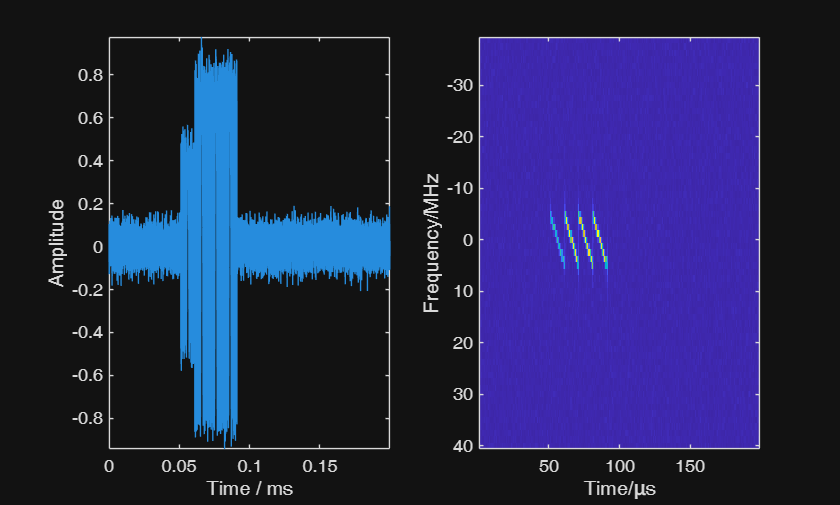

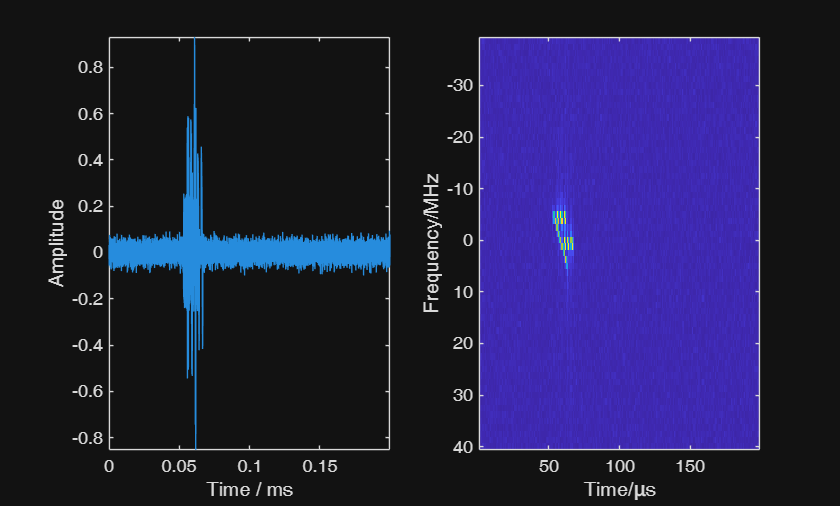

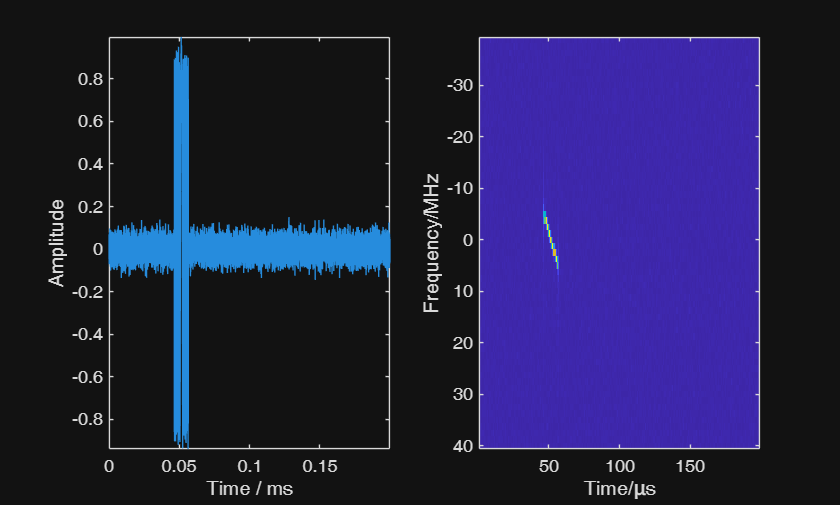

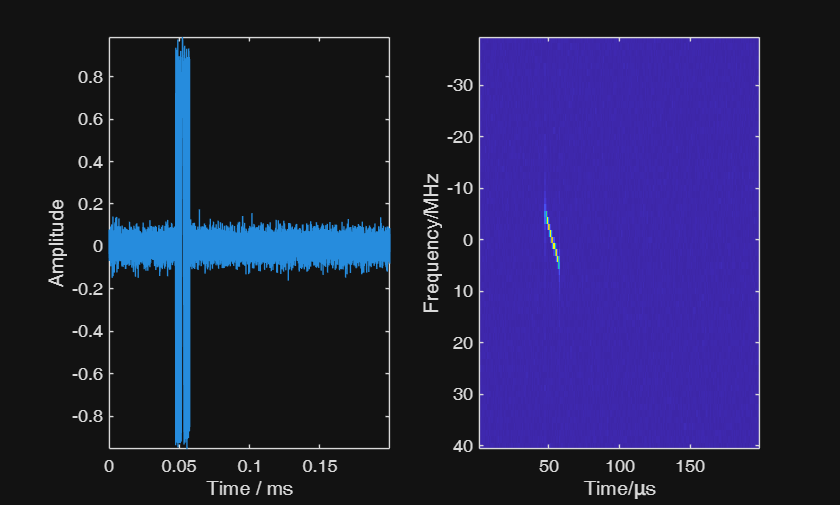

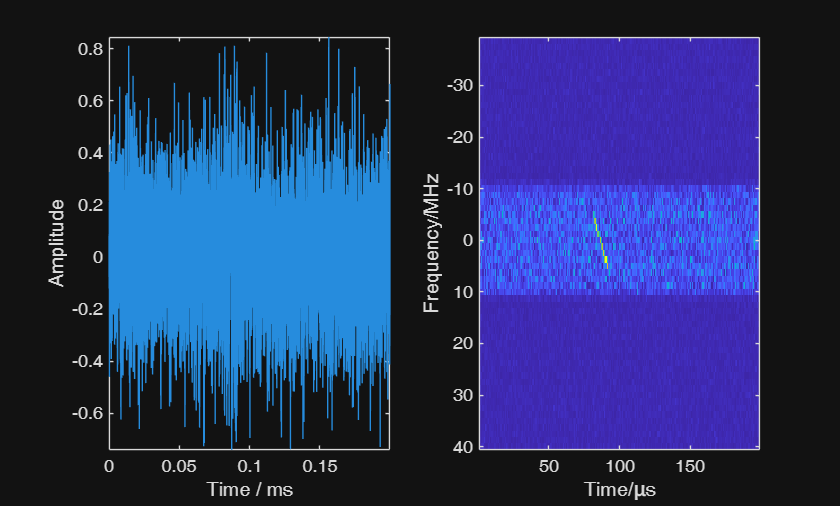

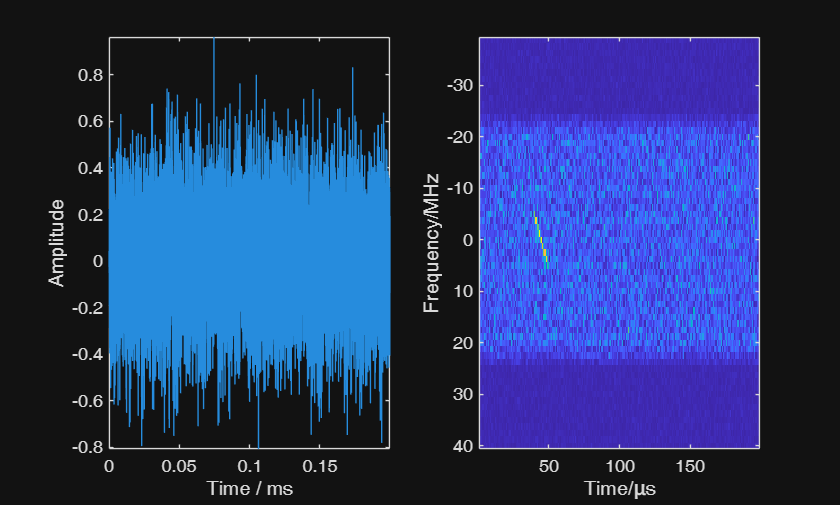

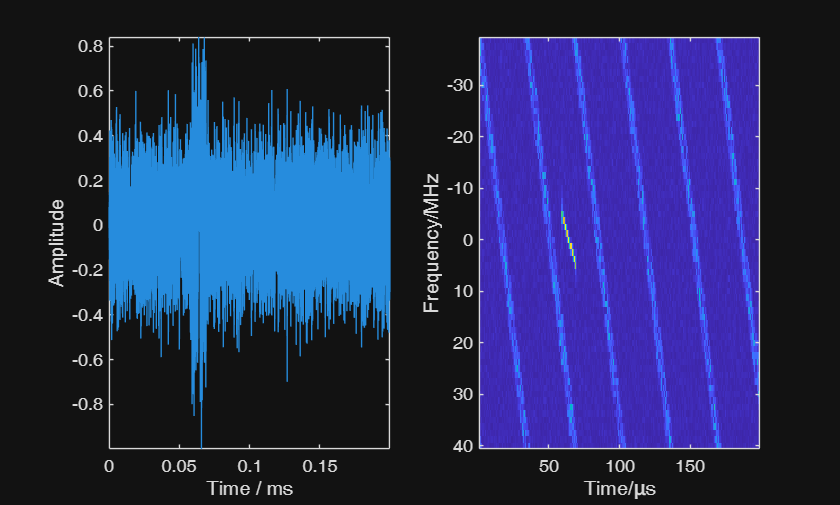

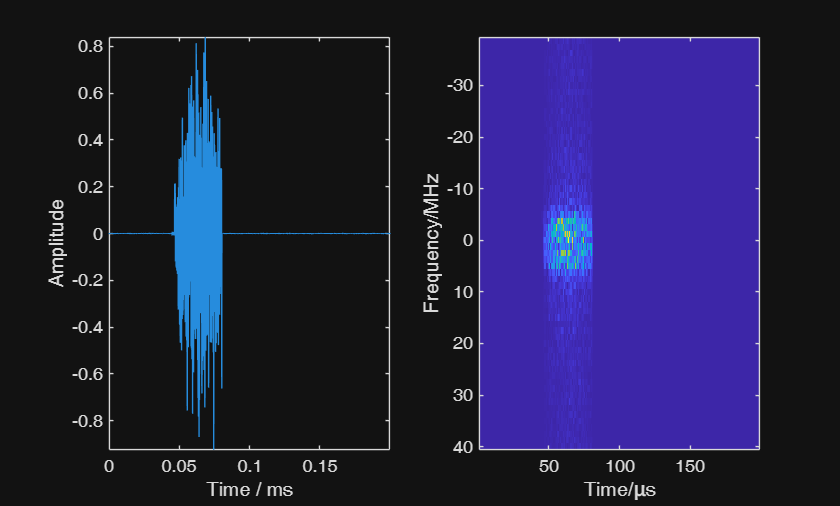

for i =1:9
rx = all_samples(50*i-49,:);
figure(i);
subplot(1,2,1);
plot(params.t_total*1e3, real(rx));
% axis([0 3.2 -1.1 1.1])
axis tight;
xlabel('Time / ms'); ylabel('Amplitude');

subplot(1,2,2);

[S,F,T] = spectrogram(rx(1:params.PRI_samp),128,128-64,64,params.fs, 'centered');
imagesc(T*1e6,F/1e6,abs(S));
xlabel('Time/μs'); ylabel('Frequency/MHz');
end

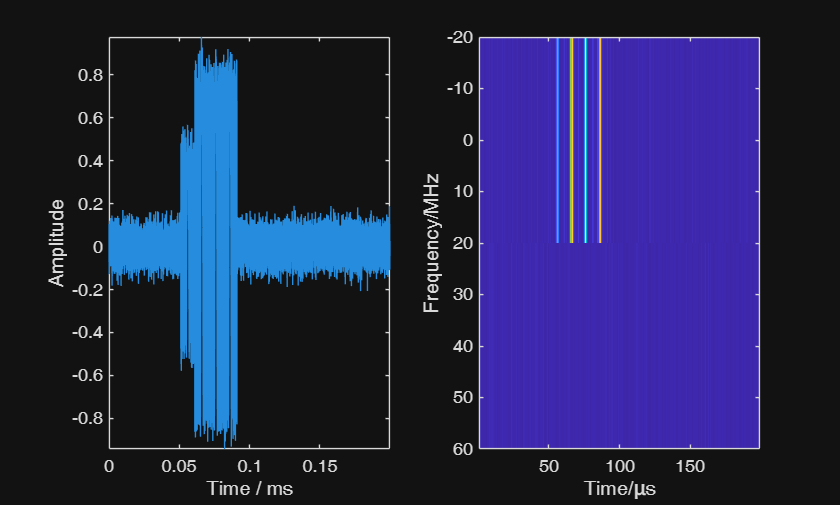

% % --- 5. 保存数据到 HDF5 文件 ---
% fprintf('总共生成了 %d 个样本。\n', size(all_samples, 1));
% output_filename = 'radar_samples.h5';
% % 将复数数据分解为实部和虚部，并转换为 single 精度
% all_samples_real = single(real(all_samples));
% all_samples_imag = single(imag(all_samples));
% all_labels_single = single(all_labels); % 标签也可以是 single 或 int
% % 确保文件不存在，否则 h5create 会报错
% if exist(output_filename, 'file')
%     delete(output_filename);
% end
% % 创建 HDF5 数据集并写入数据
% % 设置 chunking 和 compression 可以进一步优化存储和读取性能
% % 'Compression', 'gzip', 'ChunkSize', [100, size(all_samples, 2)] 是常用设置
% h5create(output_filename, '/samples_real', size(all_samples_real), 'Datatype', 'single', ...
%          'ChunkSize', [min(100, size(all_samples_real,1)), size(all_samples_real, 2)], 'Compression', 'gzip');
% h5write(output_filename, '/samples_real', all_samples_real);
% h5create(output_filename, '/samples_imag', size(all_samples_imag), 'Datatype', 'single', ...
%          'ChunkSize', [min(100, size(all_samples_imag,1)), size(all_samples_imag, 2)], 'Compression', 'gzip');
% h5write(output_filename, '/samples_imag', all_samples_imag);
% h5create(output_filename, '/labels', size(all_labels_single), 'Datatype', 'single', ...
%          'ChunkSize', [min(100, size(all_labels_single,1)), size(all_labels_single, 2)], 'Compression', 'gzip');
% h5write(output_filename, '/labels', all_labels_single);
% disp(['数据已成功保存到 ', output_filename, ' 文件中。']);
rx = all_samples(1,:);
figure(i);
subplot(1,2,1);
plot(params.t_total*1e3, real(rx));
% axis([0 3.2 -1.1 1.1])
axis tight;
xlabel('Time / ms'); ylabel('Amplitude');

subplot(1,2,2);

[S,F,T] = spectrogram(rx(1:params.PRI_samp),128,128-64,2,params.fs, 'centered');
imagesc(T*1e6,F/1e6,abs(S));
xlabel('Time/μs'); ylabel('Frequency/MHz');